% 아래와 같은 분포를 갖는 독립적인 n개의 random variables의 합으로 
% 새로운 r.v.을 생성하여 central limit theorem 확인 (새로운 r.v.의 개수= 10^7)
% Uniform Distribution (0 ≤ x ≤ 1)
% (a) n = 3      (b) n = 6      (c) n = 12      (d) n = 20
% 0부터 1사이에서 uniform distribution을 갖는 n개의 r.v.들의 합으로 새로운 r.v.을 생성한다.

## n = 3

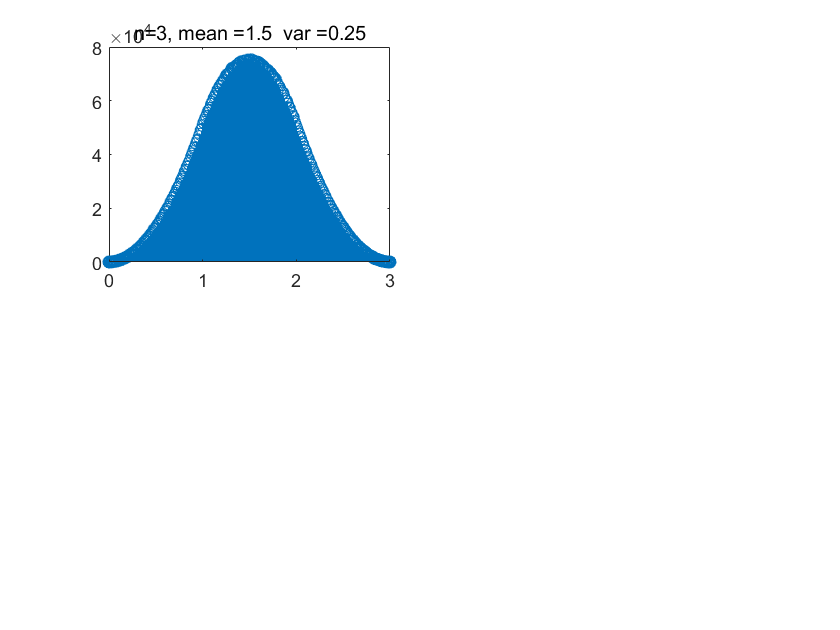

% sgtitle('Central Limit Theorem before Normalization')
arr1 = zeros(1,10^7);
for cnt = 1:3
    for i = 1:10^7
        arr1(i) = arr1(i) + rand();
    end
end
[N1,~] = histcounts(arr1);
m1 = round(mean(arr1),2); v1 = round(var(arr1),2);
subplot(2,2,1)
stem(linspace(0,3,length(N1)),N1)
title(['n=3, mean =',num2str(m1),'  var =',num2str(v1)])

% histogram(arr1) <- matlab doesn't recommand it


## n = 6

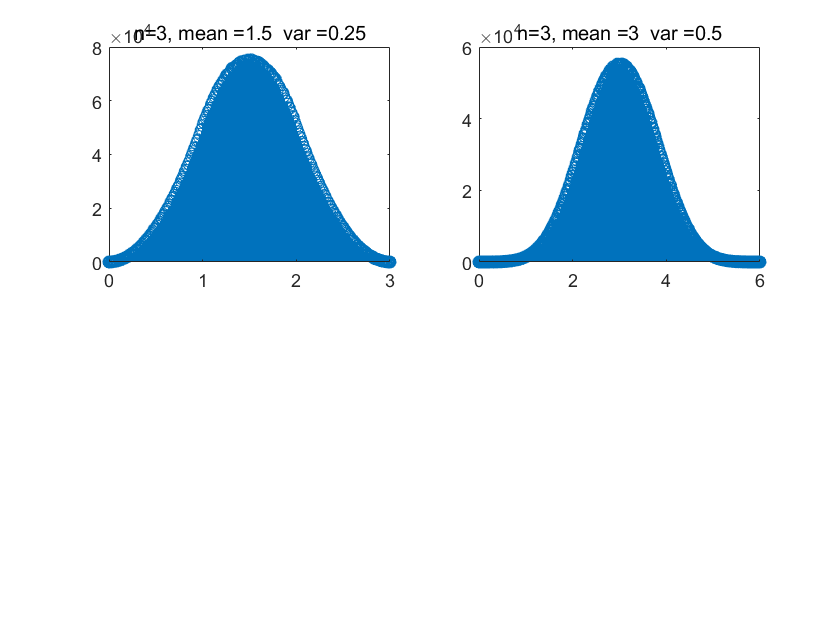

arr2 = zeros(1,10^7);
for cnt = 1:6
    for i = 1:10^7
        arr2(i) = arr2(i) + rand();
    end
end
[N2,~] = histcounts(arr2);
m2 = round(mean(arr2),2); v2 = round(var(arr2),2);
subplot(2,2,2)
stem(linspace(0,6,length(N2)),N2)
title(['n=3, mean =',num2str(m2),'  var =',num2str(v2)])

## n = 12

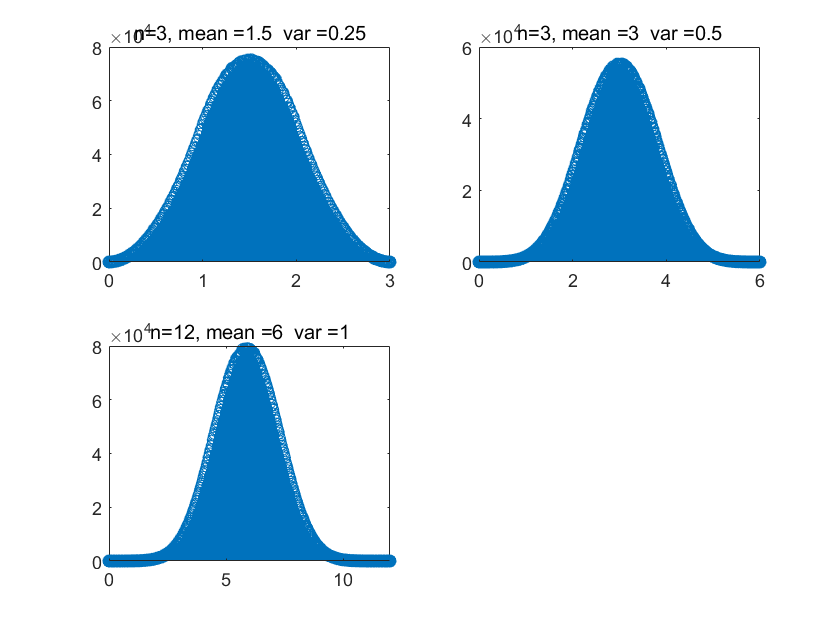

arr3 = zeros(1,10^7);
for cnt = 1:12
    for i = 1:10^7
        arr3(i) = arr3(i) + rand();
    end
end
[N3,~] = histcounts(arr3);
m3 = round(mean(arr3),2); v3 = round(var(arr3),2);
subplot(2,2,3)
stem(linspace(0,12,length(N3)),N3)
title(['n=12, mean =',num2str(m3),'  var =',num2str(v3)])
xlim([0,12])

## n = 20

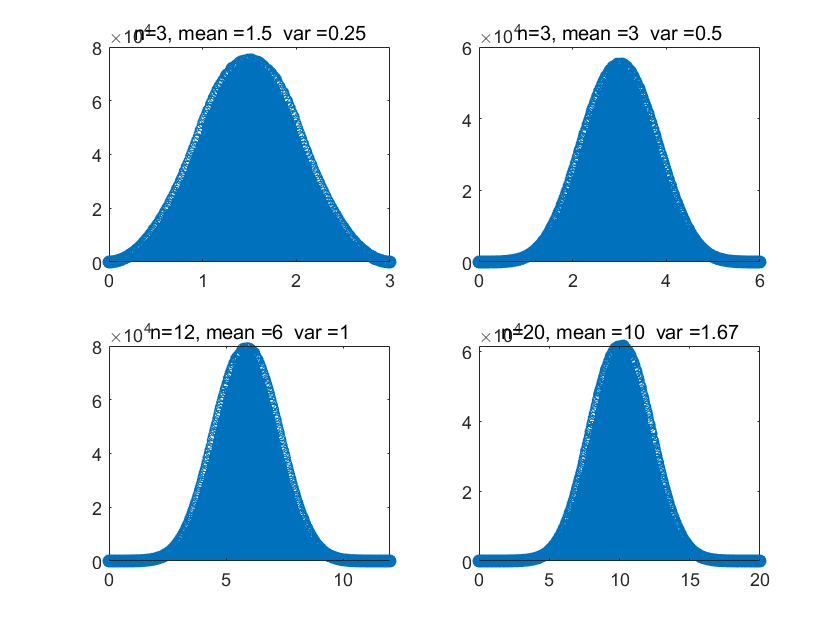

arr4 = zeros(1,10^7);
for cnt = 1:20
    for i = 1:10^7
        arr4(i) = arr4(i) + rand();
    end
end
[N4,~] = histcounts(arr4);
m4 = round(mean(arr4),2); v4 = round(var(arr4),2);
subplot(2,2,4)
stem(linspace(0,20,length(N4)),N4)
title(['n=20, mean =',num2str(m4),'  var =',num2str(v4)])